# SiSy Chapter 5 : 

# **System Modelling in Time Domain**

## Question 5-1

Figure 5-2 shows the step response of three continuous LTI systems. Which of these systems is a low-pass filter (LPF), which is a high-pass filter (HPF) and which is a band-pass filter (BPF)? Justify your answer by observing characteristics of the output signals.  

% Discussed in lecture, commented in notebook


## Question 5-2

Figure 5-3 shows the impulse response of the three LTI systems: sys1, sys2, sys3 (same as in Question 5-1). Verify in the plot if you can agree that the impulse response is the derivative of the step response, and look for a mathematical justification. 

% Discussed in lecture, commented in notebook


## **Question 5-3 **

Which test signal could you apply to a black-box continuous system in order to verify if this system is linear and time invariant (LTI)? What about the causality property, do you need a special signal to test it?

% Discussed in lecture, commented in notebook


**Question 5-4 **   

The frequency response G(f) of a system is the Fourier transform of the impulse response g(t). Confirm this relationship by taking the frequency response of a first order LPF (e.g. passive RC circuit), then take the inverse Fourier transform and compare to the impulse response (see table of reference systems in chapter 6). 

% Discussed in lecture, commented in notebook


## Example 5-6

 Execute and analyse the graphical ouput of the following Matlab script *DemoConvolution.m* showing the convolution operation of two time functions. This example is also available as a separated Matlab script (*DemoConvolution.m*) .

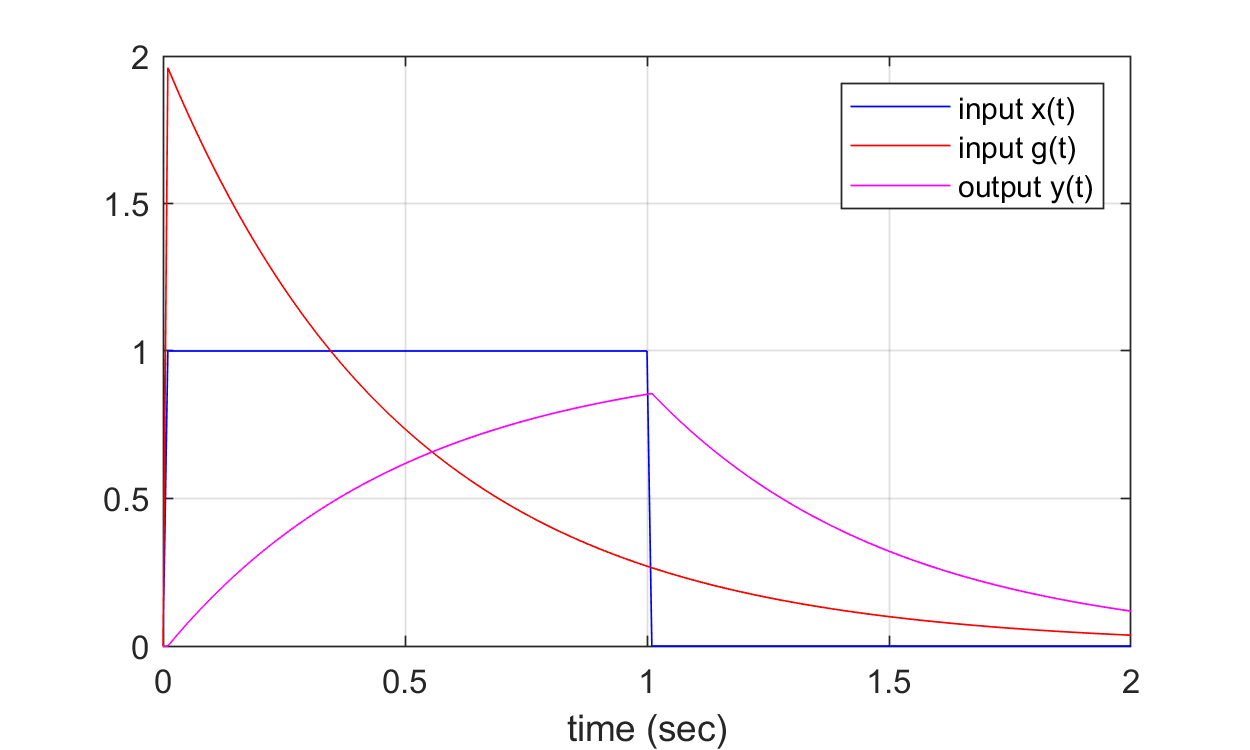

% ==========================================
% Convolution Demo
% ==========================================
clear; close all; clc;

% PARAMETERS
N=100;
Ts=1e-2;
tau = Ts*50;
time=[0:2*N]*Ts;

% FUNCTIONS 
x=[0 ones(1,N) zeros(1,N)];

% g= x;     % another option for input fct
g = 1/tau * exp(-time/tau);
g(1) = 0;  % for better visualisation of start value

y=zeros(1,2*N+1);
yconv = conv(x,g)*Ts;
% Comments/questions: 
% 1) Check the lenght of yconv vector, and explain what it comes from
% 2) How can a discrete convolution calculation approximate the continuous case?

figure('Name','Convolution-Demo: Inputs and Output','Position',[1 300 500 300]);
plot(time,x,'b',time,g,'r',time,yconv(1:2*N+1),'m'), xlabel('time (sec)')
legend({'input x(t)','input g(t)','output y(t)'}), grid on

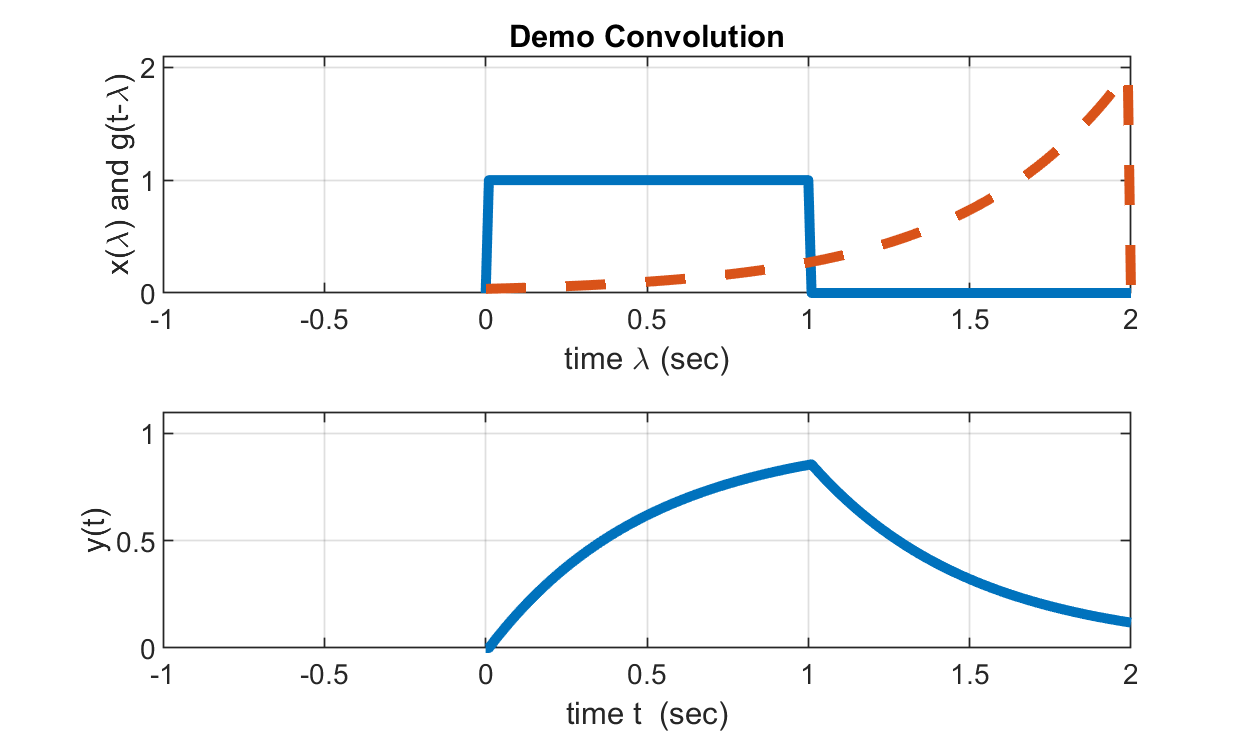

pause(2);

figure('Name','Convolution-Demo: Progression','Position',[500 300 500 300]);
grev=fliplr(g);       % flipped g(t) for plot of convolution progression
for n=1:2*N,
    subplot(2,1,1);
    plot(time,x,time-2+n*Ts,grev,'--','LineWidth',3.0); grid;
    xlabel('time \lambda (sec)'); ylabel('x(\lambda) and g(t-\lambda)'); axis([-1 2 0 2.1])
    y(1+n) = yconv(1+n);
    subplot(2,1,2);
    plot(time,y,'LineWidth',3.0); grid;
    xlabel('time t  (sec)'); ylabel('y(t)'); axis([-1 2 0 1.1])
    pause(0.01)
end
subplot(211),title('Demo Convolution')